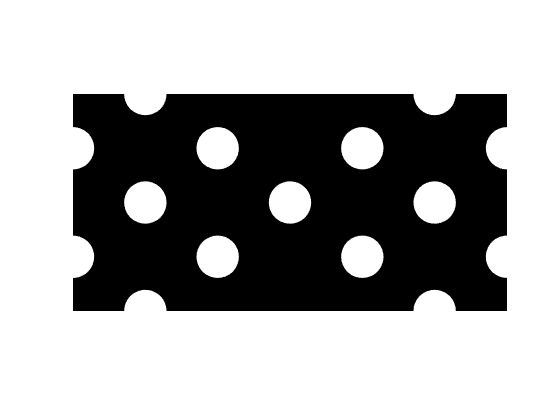

nelx=120;nely=60;volfrac=0.5;
%% LEVEL SET FUNCTION INITIALIZATION
r = nely*0.1;%RADIUS OF INITIAL HOLES
hX = nelx*[repmat([1/6,5/6],1,3),repmat([0,1/3,2/3,1],1,2),1/2];
hY = nely*[kron([0,1/2,1],ones(1,2)),kron([1/4,3/4],ones(1,4)),1/2];
[X,Y] = meshgrid(0:1:nelx,0:1:nely);
dX = bsxfun(@minus,repmat(X,[1,1,numel(hX)]),reshape(hX,1,1,numel(hX)));
dY = bsxfun(@minus,repmat(Y,[1,1,numel(hY)]),reshape(hY,1,1,numel(hY)));
Phi = max(-3,min(3,min(sqrt(dX.^2+dY.^2)-r,[],3)));
pGpX = ([Phi(:,2:end) zeros(nely+1,1)] - [zeros(nely+1,1) Phi(:,1:end-1)]);
pGpY = ([Phi(2:end,:);zeros(1,nelx+1)] - [zeros(1,nelx+1); Phi(1:end-1,:)]);
gradPhi = sqrt((pGpX).^2+(pGpY).^2);
figure(1); contourf(Phi,[0,0]);
colormap([0,0,0]); set(gcf,'color','w'); axis equal; axis off;

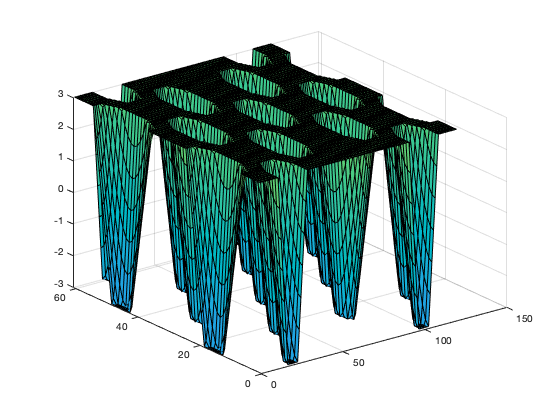

figure(2); surf(Phi); caxis([-12,12]);

%% RADIAL BASIS FUNCTION INITIALIZATION
nNode = (nely+1)*(nelx+1);
Boundary = setdiff(unique([1:1:nely+1, nNode-nely:1:nNode, ...
    nely+1:nely+1:nNode, 1:nely+1:nNode-nely]), ...
    ((nely+1)*nelx+ceil(nely/2)+1));
Phi(Boundary)=-1e-9;
Alpha = Phi(:);
Phi = reshape(Alpha,nely+1,nelx+1);
%% FINITE ELEMENT ANALYSIS PREPARATION
E0 = 1; Emin = 1e-9; nu = 0.3; %MATERIAL PROPERTIES
A11 = [12 3 -6 -3; 3 12 3 0; -6 3 12 -3; -3 0 -3 12];
A12 = [-6 -3 0 3; -3 -6 -3 -6; 0 -3 -6 3; 3 -6 3 -6];
B11 = [-4 3 -2 9; 3 -4 -9 4; -2 -9 -4 -3; 9 4 -3 -4];
B12 = [ 2 -3 4 -9; -3 2 9 -2; 4 9 2 3; -9 -2 3 2];
KE = 1/(1-nu^2)/24*([A11 A12;A12' A11]+nu*[B11 B12;B12' B11]);
eleN1 = repmat((1:nely)',1,nelx)+kron(0:nelx-1,(nely+1)*ones(nely,1));
eleNode = repmat(eleN1(:),1,4)+repmat([0,nely+[1,2],1],nelx*nely,1);
edofMat = kron(eleNode,[2,2])+repmat([-1,0],nelx*nely,4);
iK = reshape(kron(edofMat,ones(8,1))',64*nelx*nely,1);
jK = reshape(kron(edofMat,ones(1,8))',64*nelx*nely,1);
%% BOUNDARY CONDITION DEFINITION
F = sparse(2*((nely+1)*nelx+ceil(nely/2)+1),1,-100,2*nNode,1);
fixeddofs = 1:1:2*(nely+1);
freedofs = setdiff(1:2*nNode,fixeddofs);
U = zeros(2*nNode,1);
%% ITERATION OPTIMIZATION
nLoop = 500; nRelax = 30;
dt = 0.2; delta = 20; mu = 20; gamma = 0.05;
comp = zeros(nLoop,1); vol = zeros(nLoop,1);
for iT = 1:nLoop
    %% FINITE ELEMENT ANALYSIS
        [s,t] = meshgrid(-1:0.1:1,-1:0.1:1);
    tmpPhi = (1-s(:)).*(1-t(:))/4*Phi(eleNode(:,1))'+(1+s(:)).*(1-t(:))/4*...
        Phi(eleNode(:,2))'+(1+s(:)).*(1+t(:))/4*Phi(eleNode(:,3))'+...
        (1-s(:)).*(1+t(:))/4*Phi(eleNode(:,4))';
    eleVol = sum(tmpPhi>=0,1)'/numel(s);
    vol(iT) = sum(eleVol)/(nelx*nely);
    sK = reshape(KE(:)*(Emin+eleVol'*(E0-Emin)),64*nelx*nely,1);
    K = sparse(iK,jK,sK); K = (K+K')/2;
    U(freedofs,1) = K(freedofs,freedofs)\F(freedofs,1);
    eleComp = sum((U(edofMat)*KE).*U(edofMat),2).*(Emin+eleVol*(E0-Emin));
    comp(iT) = sum(eleComp);
    %% DISPLAY RESULTS
    fprintf('No.%i, Obj:%f, Vol:%f\n',[iT,comp(iT),vol(iT)]);
    figure(3); contourf(Phi,[0,0]);
    colormap([0,0,0]); set(gcf,'color','w'); axis equal; axis off;
    %saveas(gcf,sprintf('Optim_pictures/%i.png', iT));
    figure(4); surf(Phi); caxis([-12,12]);
    axis equal; axis([0,nelx,0,nely,-12,12]); view(3);
    figure(5);  subplot(2,1,1); plot(comp(1:iT),'-'); title('Compliance');
                subplot(2,1,2); plot(vol(1:iT),'-'); title('Volume fraction');
    %% CONVERGENCE CHECK
    if iT>nRelax && abs(vol(iT)-volfrac)/volfrac<1e-3 && ...
        all(abs(comp(iT)-comp(iT-9:iT-1))/comp(iT)<1e-3)
        break;
    end
    %% LAGRANGE MULTIPLIER
    if iT<=nRelax
        lag = mu*(vol(iT)-vol(1)+(vol(1)-volfrac)*iT/nRelax);
    else
        lag = lag+gamma*(vol(iT)-volfrac);
        gamma = min(gamma+0.05,5);
    end
    %% LEVEL SET FUNCTION EVOLUTION
    pGpX = ([Phi(:,2:end) zeros(nely+1,1)] - [zeros(nely+1,1) Phi(:,1:end-1)]);
    pGpY = ([Phi(2:end,:);zeros(1,nelx+1)] - [zeros(1,nelx+1); Phi(1:end-1,:)]);
    gradPhi = sqrt((pGpX).^2+(pGpY).^2);
    indexDelta = (abs(Phi(:))<=delta);
    DeltaPhi = zeros(size(Phi));
    DeltaPhi(indexDelta) = 0.75/delta*(1-Phi(indexDelta).^2/delta^2);
    eleComp = reshape(eleComp,nely,nelx);
    eleCompLR = [eleComp(:,1),eleComp]+[eleComp,eleComp(:,end)];
    nodeComp = ([eleCompLR;eleCompLR(end,:)]+[eleCompLR(1,:);eleCompLR])/4;
    B = (nodeComp(:)/median(nodeComp(:))-lag).*DeltaPhi(:)*delta/0.75;
    Alpha = Alpha+dt*B;
    Alpha = Alpha/mean(gradPhi(unique(eleNode((eleVol<1 & eleVol>0),:))));%broke the program when the body is solid, but prevent oscilations
    Phi = reshape(Alpha,nely+1,nelx+1);
    Phi(Boundary)=min(Phi(Boundary),-1e-9);
end

No.1, Obj:645429.061775, Vol:0.826694


No.2, Obj:572736.725503, Vol:0.838357


No.3, Obj:525200.223340, Vol:0.842943


No.4, Obj:499864.772233, Vol:0.838623


No.5, Obj:484603.933431, Vol:0.826511


No.6, Obj:478286.766419, Vol:0.788427


No.7, Obj:468779.785802, Vol:0.780792


No.8, Obj:470521.463751, Vol:0.758211


No.9, Obj:463634.664464, Vol:0.765476


No.10, Obj:466476.952624, Vol:0.747819


No.11, Obj:466584.252136, Vol:0.740892


No.12, Obj:469002.449959, Vol:0.729266


No.13, Obj:469684.011666, Vol:0.722969


No.14, Obj:472458.759278, Vol:0.712673


No.15, Obj:474960.649707, Vol:0.703806


No.16, Obj:478274.912447, Vol:0.694404


No.17, Obj:482687.056038, Vol:0.682875


No.18, Obj:486914.759006, Vol:0.673520


No.19, Obj:492094.304453, Vol:0.663311


No.20, Obj:501386.345454, Vol:0.647848


No.21, Obj:501630.287673, Vol:0.643668


No.22, Obj:509632.975451, Vol:0.629856


No.23, Obj:516913.847678, Vol:0.618663


No.24, Obj:522218.295049, Vol:0.609432


No.25, Obj:528173.313291, Vol:0.599359


No.26, Obj:534375.433772, Vol:0.589570


No.27, Obj:541414.986508, Vol:0.579174


No.28, Obj:548487.590153, Vol:0.569285


No.29, Obj:555633.857070, Vol:0.559953


No.30, Obj:564524.058655, Vol:0.549705


No.31, Obj:573539.294192, Vol:0.539831


No.32, Obj:578815.955392, Vol:0.532474


No.33, Obj:583941.284046, Vol:0.525794


No.34, Obj:588096.750401, Vol:0.520390


No.35, Obj:591510.975241, Vol:0.516017


No.36, Obj:594318.014902, Vol:0.512399


No.37, Obj:596865.644514, Vol:0.509186


No.38, Obj:598895.281777, Vol:0.506573


No.39, Obj:600384.126379, Vol:0.504614


No.40, Obj:601644.264877, Vol:0.502986


No.41, Obj:602603.414405, Vol:0.501736


No.42, Obj:603423.361898, Vol:0.500696


No.43, Obj:604052.532224, Vol:0.499880


No.44, Obj:604198.188575, Vol:0.499565


No.45, Obj:604424.192436, Vol:0.499198


No.46, Obj:604446.642711, Vol:0.499061


No.47, Obj:604250.264069, Vol:0.499165


No.48, Obj:603994.923237, Vol:0.499344


No.49, Obj:603909.003597, Vol:0.499342


No.50, Obj:603925.430797, Vol:0.499261


No.51, Obj:603898.207038, Vol:0.499227


No.52, Obj:604133.692272, Vol:0.498930


No.53, Obj:604286.129605, Vol:0.498714


No.54, Obj:604436.097012, Vol:0.498517


No.55, Obj:604325.716377, Vol:0.498583


No.56, Obj:604312.614735, Vol:0.498557


No.57, Obj:604214.089232, Vol:0.498626


No.58, Obj:604190.412706, Vol:0.498616


No.59, Obj:604057.236367, Vol:0.498720


No.60, Obj:604105.932848, Vol:0.498643


No.61, Obj:604193.542333, Vol:0.498530


No.62, Obj:604286.160505, Vol:0.498406


No.63, Obj:604341.151872, Vol:0.498317


No.64, Obj:604324.006175, Vol:0.498314


No.65, Obj:604173.870419, Vol:0.498445


No.66, Obj:603976.473810, Vol:0.498624


No.67, Obj:603741.061315, Vol:0.498834


No.68, Obj:603516.027329, Vol:0.499044


No.69, Obj:603223.069808, Vol:0.499321


No.70, Obj:602973.063750, Vol:0.499572


No.71, Obj:602761.259780, Vol:0.499788


No.72, Obj:602480.589163, Vol:0.500069


No.73, Obj:602180.299625, Vol:0.500371


No.74, Obj:601990.202771, Vol:0.500558


No.75, Obj:601848.685532, Vol:0.500687


No.76, Obj:601813.749696, Vol:0.500716


No.77, Obj:601772.470153, Vol:0.500745


No.78, Obj:601904.288326, Vol:0.500586


No.79, Obj:602187.853762, Vol:0.500282


No.80, Obj:602293.002844, Vol:0.500156
